# **Analysis of Solar-Panel Orientation Controlling Mechanism**

## Input

## 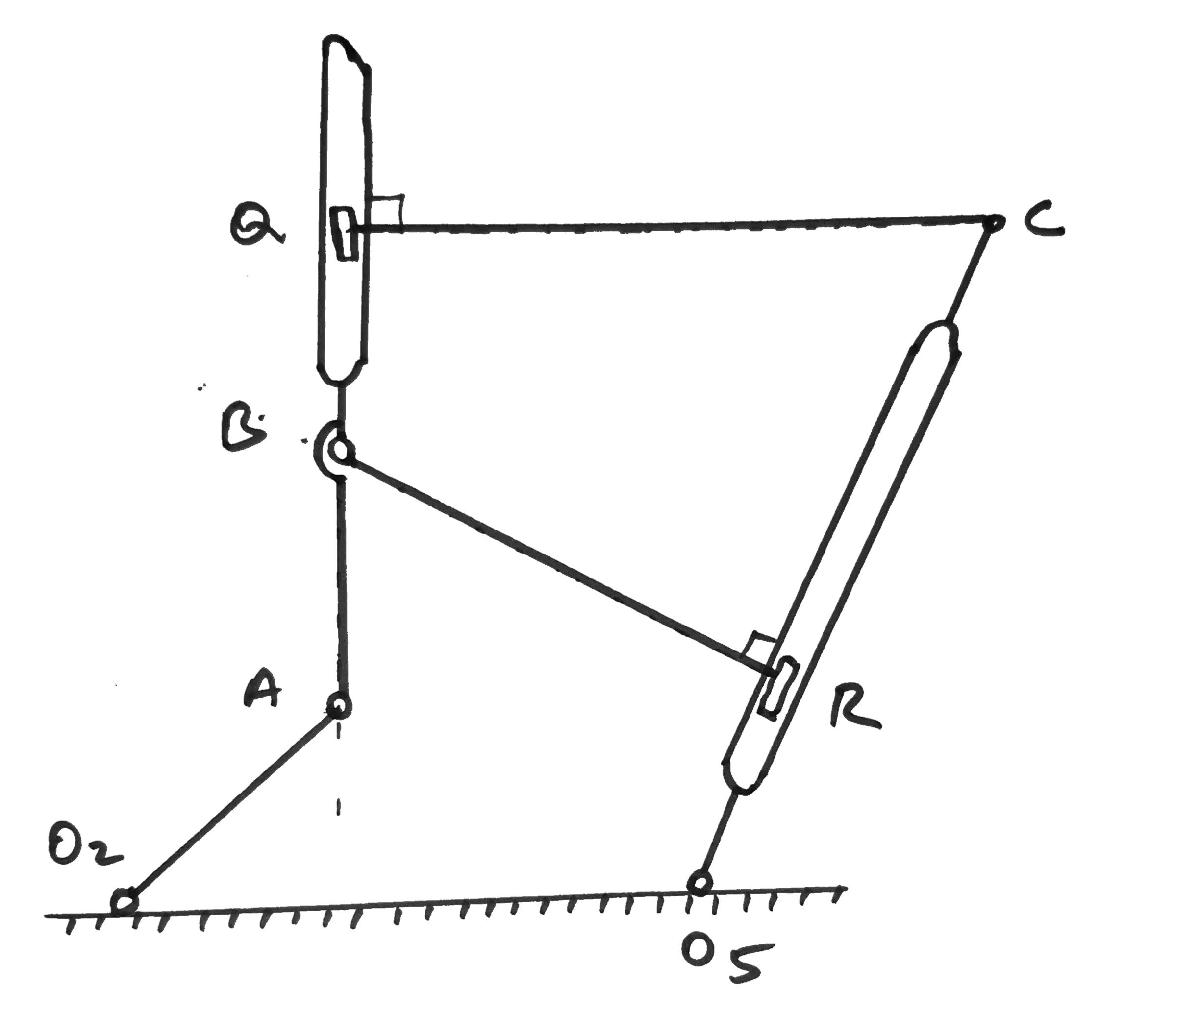

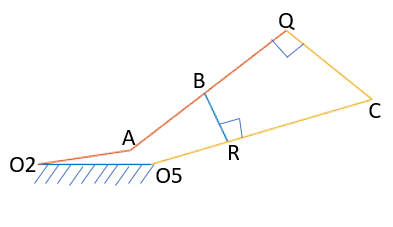

O2O5    = 60;
O2A     = 50;
AB      = 55;
O5C     = 125;
BR      = 35;
CQ      = 65;

## Calculation of Maximum input angle


        % Condition: O5R >=0 

guess_t5=30;
[t5_lim,t2_lim,A_lim,B_lim,C_lim,Q_lim,R_lim,O2_lim,O5_lim]=MaxInputNR(O2O5,O2A,AB,O5C,BR,CQ,0)

t5_lim = -28.5560

t2_lim = 62.0965

A_lim = 23.3992 + 44.1869i

B_lim = 76.7306 + 30.7423i

C_lim = 1.6979e+02 - 5.9752e+01i

Q_lim = 1.8568e+02 + 3.2759e+00i

R_lim = 60

O2_lim = 0

O5_lim = 60

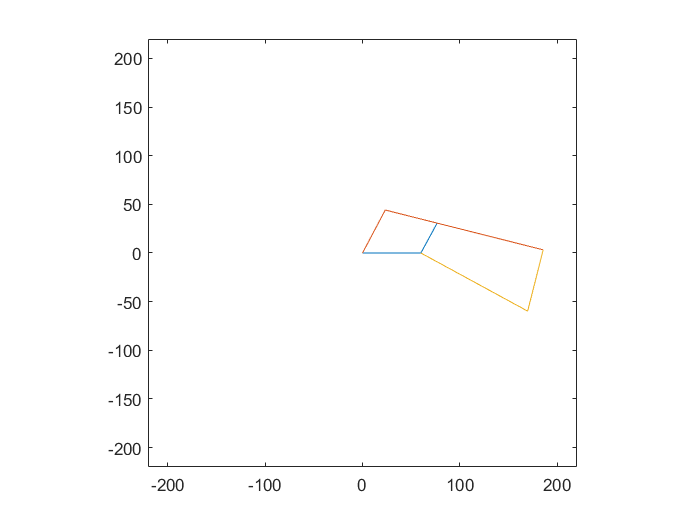

plotting(t5_lim,t2_lim,A_lim,B_lim,C_lim,Q_lim,R_lim,O2_lim,O5_lim)

Solar Tracking Mechanism at its limit (Slider R reached O5) 

## Mobility of the Mechanism

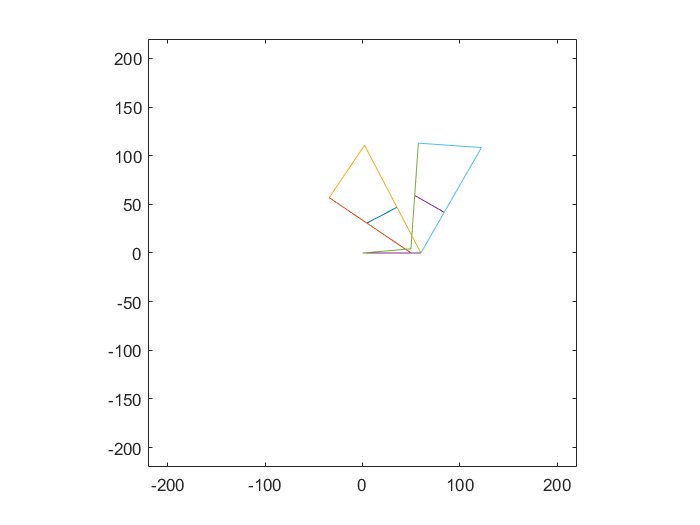

figure
guess=-50;
for t=0:5:8
    [t5,t2,A,B,C,Q,R,O2,O5]=MobilityNR(O2O5,O2A,AB,O5C,BR,CQ,t,guess);
    plotting(t5,t2,A,B,C,Q,R,O2,O5);
    hold on;
end
hold off;

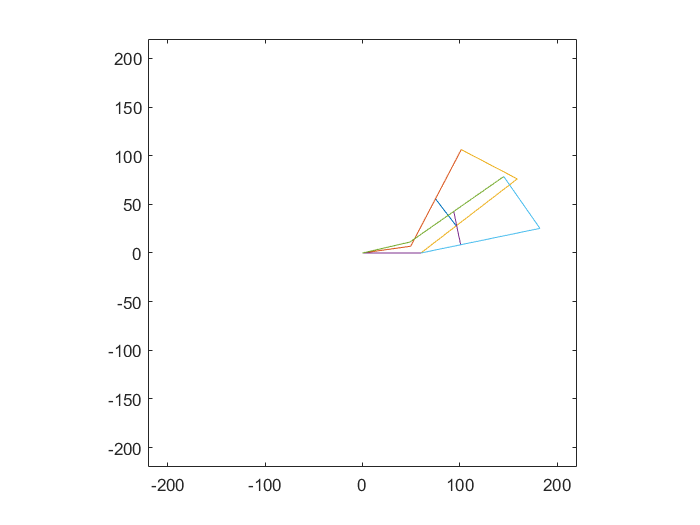

figure
guess=-50;
for t=8:5:15
    [t5,t2,A,B,C,Q,R,O2,O5]=MobilityNR(O2O5,O2A,AB,O5C,BR,CQ,t,guess);
    plotting(t5,t2,A,B,C,Q,R,O2,O5);
    hold on;
end
hold off;

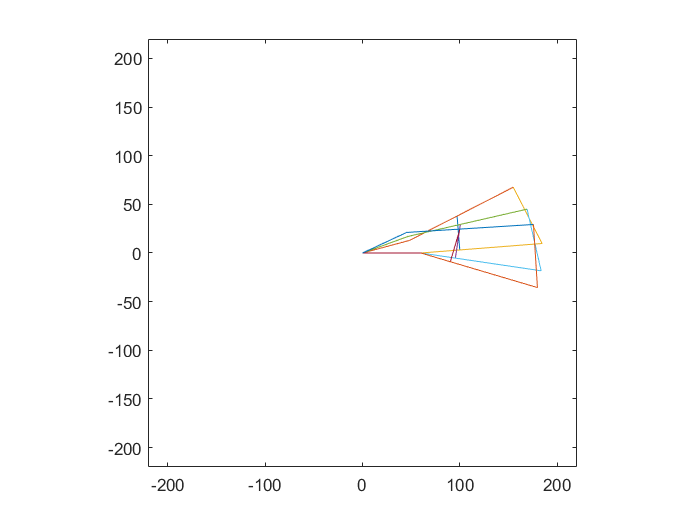

figure
guess=-50;
for t=15:5:27
    [t5,t2,A,B,C,Q,R,O2,O5]=MobilityNR(O2O5,O2A,AB,O5C,BR,CQ,t,guess);
    plotting(t5,t2,A,B,C,Q,R,O2,O5);
    hold on;
end
hold off;

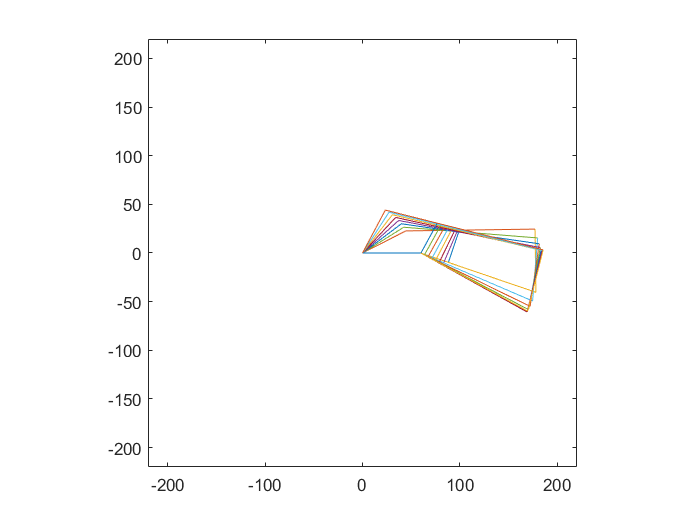

figure
guess=-50;
for t=27:5:t2_lim
    [t5,t2,A,B,C,Q,R,O2,O5]=MobilityNR(O2O5,O2A,AB,O5C,BR,CQ,t,guess);
    plotting(t5,t2,A,B,C,Q,R,O2,O5);
    hold on;
end
hold off;

% guess=-50;
% for t=0:1:4
%     [t5,t2,A,B,C,Q,R,O2,O5]=MobilityNR(O2O5,O2A,AB,O5C,BR,CQ,t,guess);
%     plotPoints(t5,t2,A,B,C,Q,R,O2,O5);
%     hold on;
% end
% hold off;

## Position Analysis

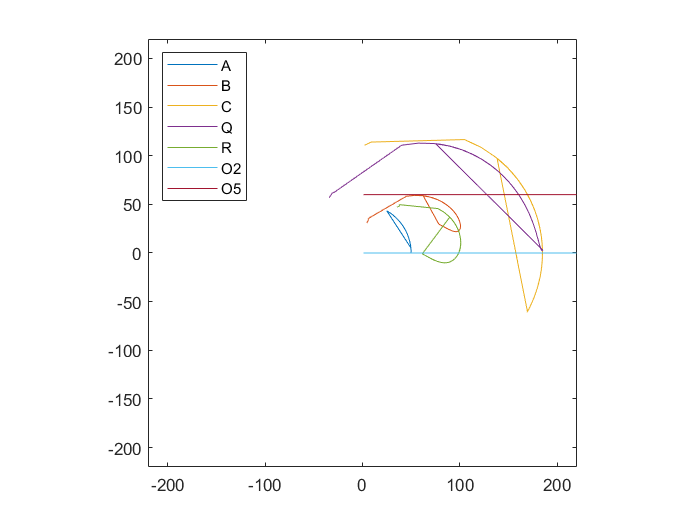


guess=-50;
for t=0:1:60
    [t5,t2,A,B,C,Q,R,O2,O5]=MobilityNR(O2O5,O2A,AB,O5C,BR,CQ,t,guess);
    AA(t+1) = A;
    BB(t+1) = B;
    CC(t+1) = C;
    QQ(t+1) = Q;
    RR(t+1) = R;
    OO2(t+1) = O2;
    OO5(t+1) = O5;
end
plotLocus(AA,BB,CC,RR,QQ,OO2,OO5)

## Input vs Output plot

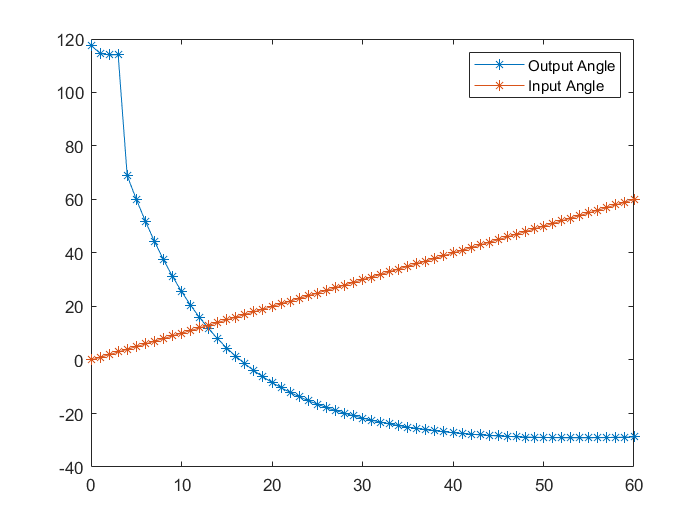

guess=-50;
for t=0:1:60
    [t5,t2,A,B,C,Q,R,O2,O5]=MobilityNR(O2O5,O2A,AB,O5C,BR,CQ,t,guess);
    tt5(t+1)=t5;
    tt2(t+1)=t2;
end
plot(tt2,tt5,'-*')
hold on;
plot(tt2,tt2,'-*')
legend('Output Angle','Input Angle')
hold off;

$\theta_2$ Vs $\theta_5$ Plot

## Analyzing Genereted Function

f=fit(tt2',tt5','exp2')

f =      General model Exp2:
     f(x) = a*exp(b*x) + c*exp(d*x)
     Coefficients (with 95% confidence bounds):
       a =      -27.92  (-38.43, -17.41)
       b =     0.00107  (-0.006495, 0.008635)
       c =       159.3  (149.5, 169.1)
       d =     -0.1054  (-0.1191, -0.09175)

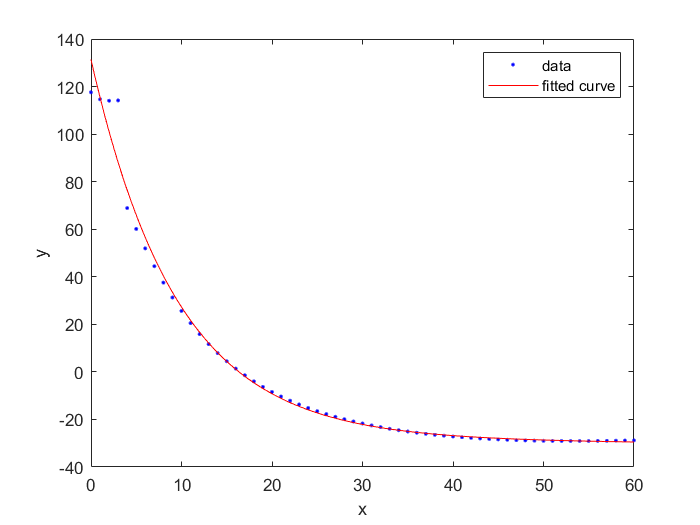

plot(f,tt2,tt5)

function er = MaxInputerror(O2O5,O2A,AB,O5C,BR,CQ,guess)
    
    guess_t5 = guess; % in degrees
    
    O2=0+0i;
    O5=O2+O2O5;
    R=O5;
    C=O5+O5C*exp(guess_t5*(pi/180)*1i);
    B=R+BR*exp((guess_t5+90)*(pi/180)*1i);
    BC=abs(C-B);
    BQ=(BC^2 - CQ^2)^0.5;
    [Q1,Q2]= circcirc(real(C),imag(C),CQ,real(B),imag(B),BQ);
    Q = Q1(2)+Q2(2)*1i;
    A = B+(AB*(B-Q)/BQ);
    %t2 = atan(imag(A)/real(AB))
    
    O2A1=abs(O2-A);
    er=abs(O2A1-O2A);
    
end

function [t5,t2,A,B,C,Q,R,O2,O5] = MaxInputNR(O2O5,O2A,AB,O5C,BR,CQ,guess)
   
    t_k = guess;
    tol=1e-10;
    while abs((MaxInputerror(O2O5,O2A,AB,O5C,BR,CQ,t_k)))>tol
        Er = MaxInputerror(O2O5,O2A,AB,O5C,BR,CQ,t_k);
        Er1 = MaxInputerror(O2O5,O2A,AB,O5C,BR,CQ,t_k+tol);
        Er_deri = ((Er1-Er)/tol);
        t_k = t_k - (Er/Er_deri);
    end
    % err=MaxInputerror(O2O5,O2A,AB,O5C,BR,CQ,t_k);
    t5=t_k;
    
    O2=0+0i;
    O5=O2+O2O5;
    R=O5;
    C=O5+O5C*exp(t5*(pi/180)*1i);
    B=R+BR*exp((t5+90)*(pi/180)*1i);
    BC=abs(C-B);
    BQ=(BC^2 - CQ^2)^0.5;
    [Q1,Q2]= circcirc(real(C),imag(C),CQ,real(B),imag(B),BQ);
    Q = Q1(2)+Q2(2)*1i;
    A = B+(AB*(B-Q)/BQ);
    t2 = (180/pi)*atan(imag(A)/real(A));
    
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function er = MobilityError(O2O5,O2A,AB,O5C,BR,CQ,t2,guess)
    
    t5 = guess;
    O2 = 0+0i;
    O5 = O2O5+0i;
    A = O2+O2A*exp((t2*pi/180)*1i);
    C = O5 + O5C*exp((t5*pi/180)*1i);
    
    AC = abs(C-A);
    AQ = (-CQ^2 + AC^2)^0.5;
    
    [Q1,Q2]= circcirc(real(C),imag(C),CQ,real(A),imag(A),AQ);
    Q = Q1(2)+Q2(2)*1i;
    
    B = A+(AB*(Q-A)/AQ);
    
    m_O5C = imag(C)/(real(C)-real(O5));
    BR1 = abs((m_O5C*real(B)-imag(B)-m_O5C*O2O5)/((1+m_O5C^2)^0.5));
    
    er = abs(BR1-BR);

end

function [t5,t2,A,B,C,Q,R,O2,O5] = MobilityNR(O2O5,O2A,AB,O5C,BR,CQ,t2,guess)
   
    t_k = guess;
    tol=1e-10;
    while abs((MobilityError(O2O5,O2A,AB,O5C,BR,CQ,t2,t_k)))>tol
        Er = MobilityError(O2O5,O2A,AB,O5C,BR,CQ,t2,t_k);
        Er1 = MobilityError(O2O5,O2A,AB,O5C,BR,CQ,t2,t_k+tol);
        Er_deri = ((Er1-Er)/tol);
        t_k = t_k - (Er/Er_deri);
    end
    % err=MaxInputerror(O2O5,O2A,AB,O5C,BR,CQ,t_k);
    t5=t_k;
    O2 = 0+0i;
    O5 = O2O5+0i;
    A = O2+O2A*exp((t2*pi/180)*1i);
    C = O5 + O5C*exp((t5*pi/180)*1i);
    AC = abs(C-A);
    AQ = (-CQ^2 + AC^2)^0.5;
    [Q1,Q2]= circcirc(real(C),imag(C),CQ,real(A),imag(A),AQ);
    Q = Q1(2)+Q2(2)*1i;
    B = A+(AB*(Q-A)/AQ);
    m_O5C = imag(C)/(real(C)-real(O5));
    BR = abs((m_O5C*real(B)-imag(B)-m_O5C*O2O5)/((1+m_O5C^2)^0.5));
    BO5 = abs(B-O5);
    O5R = (BO5^2 - BR^2)^0.5;
    R = O5 + O5R*exp((t5*pi/180)*1i); 
    
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function []=plotting(t5,t2,A,B,C,Q,R,O2,O5)
         plot([R B A O2 O5],'-');
         hold on;
         xlim([-220 220]);
         ylim([-220 220]);
         plot([O2 A B Q]);
         plot([O5 R C Q],'-')
         pbaspect([1 1 1])
         hold off;
end

function []=plotPoints(t5,t2,A,B,C,Q,R,O2,O5)
         plot([R B A O2 O5 C Q],'*');
         hold on;
         xlim([-220 220]);
         ylim([-220 220]);
         pbaspect([1 1 1])
         hold off;
end

function []=plotLocus(AA,BB,CC,RR,QQ,OO2,OO5)
        plot(AA)
        hold on;
        plot(BB)
        plot(CC)
        plot(QQ)
        plot(RR)
        plot(OO2)
        plot(OO5)
        xlim([-220 220]);
        ylim([-220 220]);
        pbaspect([1 1 1])
        legend('A','B','C','Q','R','O2','O5','Location','northwest')
        hold off;
end


-